# [Additive Manufacturing](https://apmonitor.com/pds/index.php/Main/AdditiveManufacturing)

Additive manufacturing is the process of building from a computer controlled 3-dimensional printer. The material can be polymer (plastic), ceramic, metallic powder, liquid, or any material that is joined together through deposition, solidification, or fusion. It speeds the development of prototypes by precisely converting a computer aided design (CAD) drawing into a physical device. Additive manufacturing can be either a prototype or scaled up to full product production, but typically for applications that require customization or with low production volumes.

**Background:** A [3D print data set of additive manufacturing test conditions](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is available for Polylactic Acid (PLA) and Acrylonitrile Butadiene Styrene (ABS). PLA can print at lower temperatures of 180°C compared to 250°C for ABS. PLA is more brittle than ABS and is not typically suitable for high strength applications. The data was collected by researchers in the Mechanical Engineering department at Selçuk Üniversitesi on a Ultimaker S5 3D printer. The study focused on how the parameters in a specific 3D printer affects the print quality, accuracy and final part strength. This work is based on the settings and PLA or ABS filaments. Material and strength tests were carried out on a Sincotec GMBH tester capable of pulling 20 kN.

Nine parameters were adjusted for the Ultimaker S5 3D printer.

- Layer Height (mm)

- Wall Thickness (mm)

- Infill Density (%)

- Infill Pattern (Honeycomb or Grid)

- Nozzle Temperature (ºC)

- Bed Temperature (ºC)

- Print Speed (mm/s)

- Material (PLA or ABS)

- Fan Speed (%)

After the part was manufactured, three parameters were measured for each product.

- Roughness (µm)

- Tension Strength (MPa)

- Elongation (%)

The labeled data is a combination of PLA and ABS material, print patterns, and conditions with 66 samples from a first repository and 50 samples from a second repository. The [combined set](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is 70 samples with the duplicates removed and one outlier added. The label associated with each filament is *pla* or *abs*. The print pattern is *grid* or *honeycomb*. [One-hot encoding](https://en.wikipedia.org/wiki/One-hot) translates character labels into a binary representation (0 or 1) for classification.

## Part 1: Data Visualization and Cleansing

Generate summary statistics with a profiling report to [statistically characterize the data](https://apmonitor.com/pds/index.php/Main/StatisticsMath). Use box plots to identify the one outlier in the data. Remove the row that contains the outlier from the data set. Generate a pair plot and correlation matrix. What factors are highly correlated to *Material (PLA or ABS)* and *Tension Strength (MPa)*?

 [Additive Manufacturing Data](https://apmonitor.com/pds/uploads/Main/manufacturing.txt)

% Clear preceeding data 
clear;
% Load data from URL 
url = "https://apmonitor.com/pds/uploads/Main/manufacturing.txt";
data = readtable(url);

% Change and store variable names
parameters = ["Layer Height" "Wall Thickness" "Infill Density" ...
            "Infill Pattern" "Nozzle Temperature" "Bed Temperature" ...
            "Print Speed" "Material" "Fan Speed" ...
            "Roughness" "Tension Strength" "Elongation"];
data.Properties.VariableNames = parameters;

Live Editor tasks are a great way to perform a specific set of operations, such as creating a plot. You can add tasks to live scripts to explore parameters and automatically generate code. To add a task to a live script, go to the **Live Editor** tab, click **Task**, and select from the available tasks.

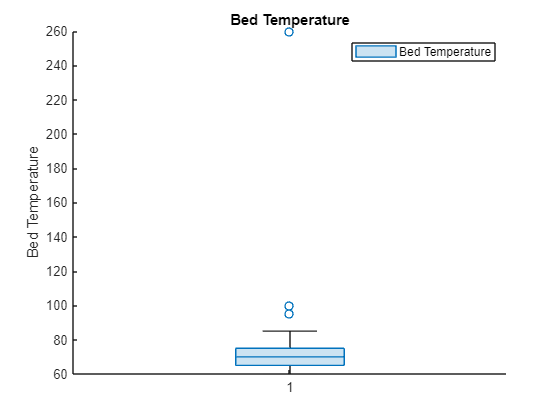

% Create boxchart of data.("Bed Temperature")
h2 = boxchart(data.("Bed Temperature"),"DisplayName","Bed Temperature");

% Add ylabel, title, and legend
ylabel("Bed Temperature")
title("Bed Temperature")
legend

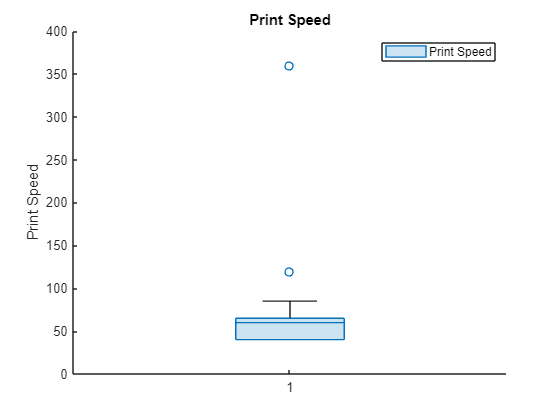

% Create boxchart of data.("Print Speed")
h = boxchart(data.("Print Speed"),"DisplayName","Print Speed");

% Add ylabel, title, and legend
ylabel("Print Speed")
title("Print Speed")
legend


% Fill outliers
[cleaned, TFrm] = rmoutliers(data.("Bed Temperature"),"Percentile", [2 97]);

data_clean = data(~TFrm,:);

% Create boxchart of data_clean.("Bed Temperature")
h3 = boxchart(data_clean.("Bed Temperature"),"DisplayName","Bed Temperature");

% Add ylabel, title, and legend
ylabel("Bed Temperature")
title("Bed Temperature")
legend
% Make labels for better visibility on the pair plot
PlotLabels = ["Layer Height" "Thickness" "Infill Density" ...
            "Infill Pattern" "Nozzle T." "Bed T." ...
            "Print Speed" "Material" "Fan Speed" ...
            "Roughness" "Strength" "Elongation"];

% Make categorical data numerical for plotting
data_clean.MaterialLabel = data_clean.Material

data_clean = 68×13 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material    Fan Speed    Roughness    Tension Strength    Elongation    MaterialLabel
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    ________    _________    _________    ________________    __________    _____________

        0.02               8                90          {'grid'     }            220                

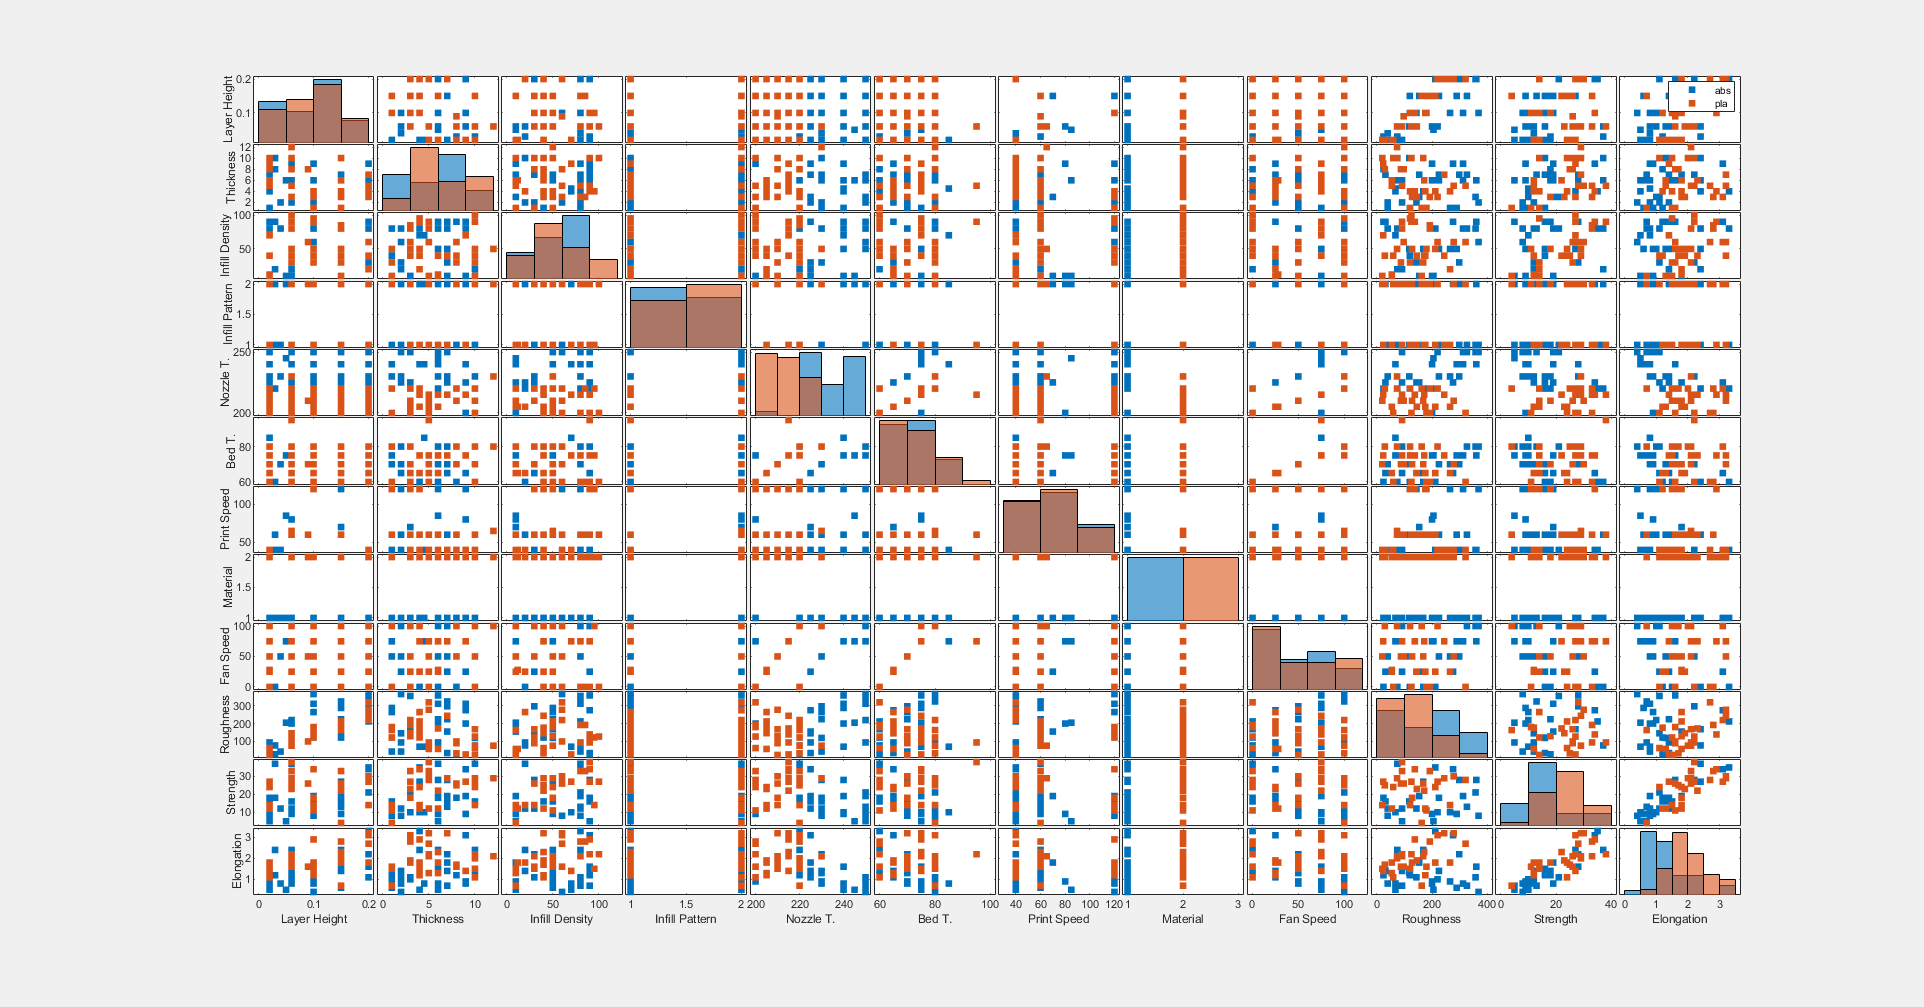

data_clean.Material = categorical(data_clean.Material, {'abs','pla'},{'0','1'});
data_clean.Material=double(data_clean.Material);
data_clean.("Infill Pattern") = categorical(data_clean.("Infill Pattern"), {'grid','honeycomb'},{'0','1'});
data_clean.("Infill Pattern") = double(data_clean.("Infill Pattern"));

% Generate a pair plot 
close all;
fig = figure('Position', [0,0,12000,12000]);
set(fig, 'Visible', 'on');
gplotmatrix(table2array(data_clean(:,1:end-1)),[], cell2mat(data_clean.MaterialLabel), [],[],[],[], 'grpbars', PlotLabels);

The generated pair plot is difficult to read in the inline output so be sure to view it in a separate window. In the pair plot we have every column plotted against every other column. When the column is plotted against itself we get a histogram showing the frequency distribution of the column. ABS data points are blue while PLA data points are red. One of the strongest correlations is between strength and elongation, the stronger the material is the more it is able to elongate under pressure. We can also see that we have an equal number of samples from each material. In general PLA has more strength and elongation, while ABS has more roughness. 

% Delete MaterialLabel column because it is no longer useful
data_clean.MaterialLabel = [];

% Print Statistics Values
for i = 1:numel(parameters)
    parameter = parameters{i};
    disp(parameter)
    disp(statistics(data_clean.(parameter)))
end

Layer Height


    count: 68
     mean: 0.0976
      std: 0.0618
      min: 0.0200
      max: 0.2000
       Q1: 0.0550
       Q2: 0.1000
       Q3: 0.1500



Wall Thickness


    count: 68
     mean: 5.4632
      std: 2.9464
      min: 1
      max: 12
       Q1: 3
       Q2: 5.5000
       Q3: 8



Infill Density


    count: 68
     mean: 53.5588
      std: 27.6526
      min: 10
      max: 100
       Q1: 30
       Q2: 50
       Q3: 80



Infill Pattern


    count: 68
     mean: 1.5147
      std: 0.5035
      min: 1
      max: 2
       Q1: 1
       Q2: 2
       Q3: 2



Nozzle Temperature


    count: 68
     mean: 221.4706
      std: 14.6364
      min: 200
      max: 250
       Q1: 210
       Q2: 220
       Q3: 230



Bed Temperature


    count: 68
     mean: 70.0735
      std: 7.8461
      min: 60
      max: 95
       Q1: 65
       Q2: 70
       Q3: 75



Print Speed


    count: 68
     mean: 65
      std: 28.9750
      min: 40
      max: 120
       Q1: 40
       Q2: 60
       Q3: 62.5000



Material


    count: 68
     mean: 1.4853
      std: 0.5035
      min: 1
      max: 2
       Q1: 1
       Q2: 1
       Q3: 2



Fan Speed


    count: 68
     mean: 48.5735
      std: 35.5596
      min: 0
      max: 100
       Q1: 25
       Q2: 50
       Q3: 75



Roughness


    count: 68
     mean: 158.3235
      std: 95.3004
      min: 21
      max: 368
       Q1: 75
       Q2: 144.5000
       Q3: 220



Tension Strength


    count: 68
     mean: 19.9706
      std: 9.1030
      min: 4
      max: 38
       Q1: 12
       Q2: 18.5000
       Q3: 27



Elongation


    count: 68
     mean: 1.6353
      std: 0.7499
      min: 0.4000
      max: 3.3000
       Q1: 1.1000
       Q2: 1.5000
       Q3: 2.1500



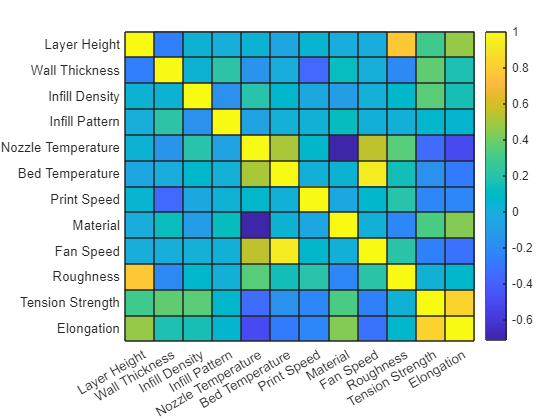

% Create correlation matrix 
R = corrcoef(table2array(data_clean));

% Plot the heat map
figure;
heatmap(data_clean.Properties.VariableNames, data_clean.Properties.VariableNames, R,'Colormap',parula)

## Part 2: Prediction and Analysis

Examination of a Spearman's "rho" based correlation matrix versus the one presented above based on R^2 values shows little change. We are primarily interested in predicting material and tension strength. For material, nozzle temperature and elongation seem to have the strongest correlations. For tension strength the strongest correlates are layer height, nozzle temperature, and material; disregarding elongation as it is not a specifiable machine input.

% Scale Data 
disp(data_clean)

    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material    Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    ________    _________    _________    ________________    __________

        0.02               8                90                1                  220                  60                40           1             0           25              18              1.

sc_data = rescale(table2array(data_clean))

sc_data =     0.0001    0.0217    0.2446    0.0027    0.5978    0.1630    0.1087    0.0027         0    0.0679    0.0489    0.0033
    0.0001    0.0190    0.2446    0.0054    0.6114    0.1766    0.1087    0.0027    0.0679    0.0870    0.0435    0.0038
    0.0001    0.0027    0.2174    0.0027    0.6250    0.1902    0.1087    0.0027    0.1359    0.1087    0.0217    0.0022
    0.0001    0.0109    0.1902    0.0054    0.6522    0.2038    0.1087    0.0027    0.2038    0.1848    0.0272    0.0014
    0.0001    0.0163    0.2446    0.0027    0.6793    0.2174    0.1087    0.0027    0.2717    0.2500    0.0136    0.0019
    0.0001    0.0272    0.1087    0.0054    0.5435    0.1630    0.1087    0.0054         0    0.1630    0.0652    0.0030
    0.0001    0.0136    0.0272    0.0027    0.5571    0.1766    0.1087    0.0054    0.0679    0.1495    0.0326    0.0035
    0.0001    0.0272    0.0272    0.0054    0.5707    0.1902    0.1087    0.0054    0.1359    0.0571    0.0380    0.0041
    0.0001    0.0245  

% Make the array into a table again
sc_data = array2table(sc_data)

sc_data = 68×12 table
     sc_data1     sc_data2     sc_data3    sc_data4     sc_data5    sc_data6    sc_data7    sc_data8     sc_data9    sc_data10    sc_data11    sc_data12
    __________    _________    ________    _________    ________    ________    ________    _________    ________    _________    _________    _________

    5.4348e-05     0.021739     0.24457    0.0027174    0.59783     0.16304      0.1087     0.0027174           0    0.067935     0.048913     0.0032609
    5.4348e-05     0.019022     0.24457    0.0054348    0.61141     0.17663      0.1087     0.0027174    0.067

% Rename the variables with the correct names
sc_data.Properties.VariableNames = data_clean.Properties.VariableNames

sc_data = 68×12 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.021739           0.24457         0.0027174            0.59783              0.16304           0.1087      0.0027174           0     0.067935     

% Implement 80/20 train/test split
[r,c] = size(sc_data) % Get the number of rows and columns

r = 68

c = 12

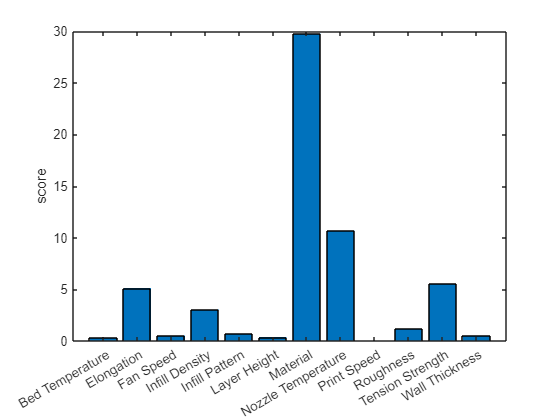

cv = cvpartition(r,'HoldOut',0.20); % Create a partition to split the data
idx = cv.test; % Get the testing index

% Assign testing and training data
trainData = sc_data(~idx,:);
testData = sc_data(idx,:);

% Use chi-squared statistic to find the importance of each feature in
% predicting the Material
[idx, scores] = fscchi2(trainData,trainData.Material);
% Make the variable names categorical for plotting
X = categorical(trainData.Properties.VariableNames);
% Plot Z scores
figure;
bar(X,scores)
ylabel('score')

The score in the bar chart above is the negative log of the p-value of the feature in terms of its correlation with the material. A higher score means a higher correlation between the two variables, which means that feature is more useful for predicting the material. 

### Perform Predictions

#### Naive Bayes

nb = fitcnb(trainData, 'Material')

nb =   ClassificationNaiveBayes
            PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
              ResponseName: 'Material'
     CategoricalPredictors: []
                ClassNames: [0.0027 0.0054]
            ScoreTransform: 'none'
           NumObservations: 55
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×11 cell}


  Properties, Methods


#### Nearest Neighbors

knn = fitcknn(trainData,'Material')

knn =   ClassificationKNN
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 55
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


#### Classification Tree

tree = fitctree(trainData,'Material')

tree =   ClassificationTree
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 55


  Properties, Methods


#### Discriminant Analysis

disc = fitcdiscr(trainData, 'Material')

disc =   ClassificationDiscriminant
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 55
              DiscrimType: 'linear'
                       Mu: [2×11 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


#### Support Vector Machine Classification

vect = fitcsvm(trainData,'Material')

vect =   ClassificationSVM
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 55
                    Alpha: [54×1 double]
                     Bias: 1.8677
         KernelParameters: [1×1 struct]
           BoxConstraints: [55×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [55×1 logical]
                   Solver: 'SMO'


  Properties, Methods


#### Classification Ensemble

ensemble = fitcensemble(trainData,'Material')

ensemble =   ClassificationEnsemble
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 55
               NumTrained: 100
                   Method: 'LogitBoost'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: [100×1 double]
       FitInfoDescription: {2×1 cell}


  Properties, Methods


#### Neural Network

nn = fitcnet(trainData,'Material')

nn =   ClassificationNeuralNetwork
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 55
               LayerSizes: 10
              Activations: 'relu'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [55×7 table]


  Properties, Methods


#### Generalized Additive Model

genadd = fitcgam(trainData,'Material')

genadd =   ClassificationGAM
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Fan Speed'  'Roughness'  'Tension Strength'  'Elongation'}
             ResponseName: 'Material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'logit'
                Intercept: 0.0657
          NumObservations: 55


  Properties, Methods


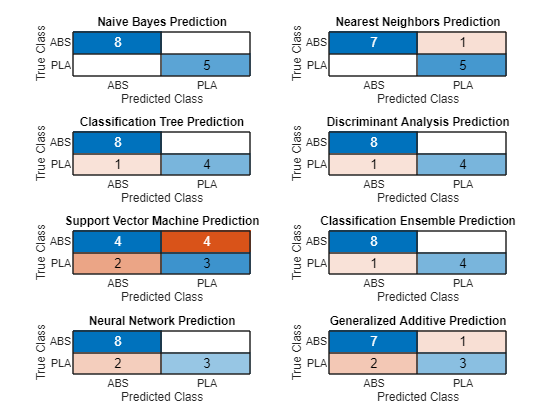

% Chart the results
titles = {'Naive Bayes Prediction' 'Nearest Neighbors Prediction' 'Classification Tree Prediction' ...
          'Discriminant Analysis Prediction' 'Support Vector Machine Prediction' 'Classification Ensemble Prediction'...
          'Neural Network Prediction' 'Generalized Additive Prediction'};

models = {nb, knn, tree, disc, vect, ensemble, nn, genadd};

figure;
tiledlayout(4,2)
for i = 1:length(models)
    % Predict the material
    labels = predict(models{i}, testData);
    
    % Change the numbers to names of the material
    idx_pla = (labels > 0.005);
    labels = string(labels);
    labels(idx_pla) = "PLA";
    labels(~idx_pla) = 'ABS';
    nexttile
    
    % Get the material names of the true labels
    idx_abs = (testData.Material < 0.005);
    true_labels = ones(length(testData.Material),1);
    true_labels = string(true_labels);
    true_labels(idx_abs) = 'ABS';
    true_labels(~idx_abs) = 'PLA';
    
    % Create the confusionchart
    confusionchart(true_labels,labels)
    title(titles{i})
end

**Analysis**

The predictions vary with each run through of the code but the classifiers tend to predict fairly well, with just a few missclassifications from most classifiers. In general, the discriminant analysis, neural network, and nearest neighbors classifiers are the most accurate. 

### **Regression Practice**

 Use 3 regression methods. Possible [regression methods](https://apmonitor.com/pds/notebooks/06_regression.html) are:

- [Linear Regression](https://apmonitor.com/pds/index.php/Main/LinearRegression)

- [Neural Network (Deep Learning)](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork)

- [K-Nearest Neighbors](https://apmonitor.com/pds/index.php/Main/KNearestNeighborsRegression)

- [Support Vector Regressor](https://apmonitor.com/pds/index.php/Main/SupportVectorRegressor)

- [XGBoost Regressor](https://apmonitor.com/pds/index.php/Main/XGBoostRegressor)

There is concern that PLA has less strength than ABS for additive manufacturing. Compare the PLA and ABS predicted strength for all of the test points. One way to compare the strength is to change the *PLA* material to *ABS* and recalculate the predicted *Tension Strength (MPa)*.

Examples chosen: Linear Regression, Neural Network, K-Nearest Neighbors 

% Use Tension strength data

% Obtain all data from layer height to tension strength
lm_input = trainData(:,1:11) 

lm_input = 55×11 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________

     5.4348e-05        0.021739           0.24457         0.0027174            0.59783              0.16304           0.1087      0.0027174           0     0.067935         0.048913    
     5.4348e-05       0.0027174           0.

#### Linear Regression

mdl = fitlm(lm_input)

mdl = Linear regression model:
    Tension Strength ~ 1 + Layer Height + Wall Thickness + Infill Density + Infill Pattern + Nozzle Temperature + Bed Temperature + Print Speed + Material + Fan Speed + Roughness

Estimated Coefficients:
                          Estimate        SE        tStat        pValue  
                          _________    ________    ________    __________

    (Intercept)           -0.081476     0.13587    -0.59964       0.55182
    Layer Height             108.64      27.825      3.9043    0.00032085
    Wall Thickness           1.3379     0.33591       3.983    0.00025189
    Infill Density          0.10349    0.033295      3.1084     0.0032927
    Infill Pattern          0.66232      1.8341     0.36112       0.71974
    Nozzle Temper

% Make predictions using the model and test data
predictions = predict(mdl,testData(:,1:10))

predictions =     0.0610
    0.0387
    0.0212
    0.0100
    0.0510
    0.0636
    0.0845
    0.0613
    0.0664
    0.0656


% Get the R squared value between the predictions and the actual data
r = corrcoef(predictions, table2array(testData(:,11)));
r = r(1,2);
R_squared_lr = r^2;
fprintf("R squared: %.2f", R_squared_lr)

R squared: 0.53

#### Neural Network Regressor

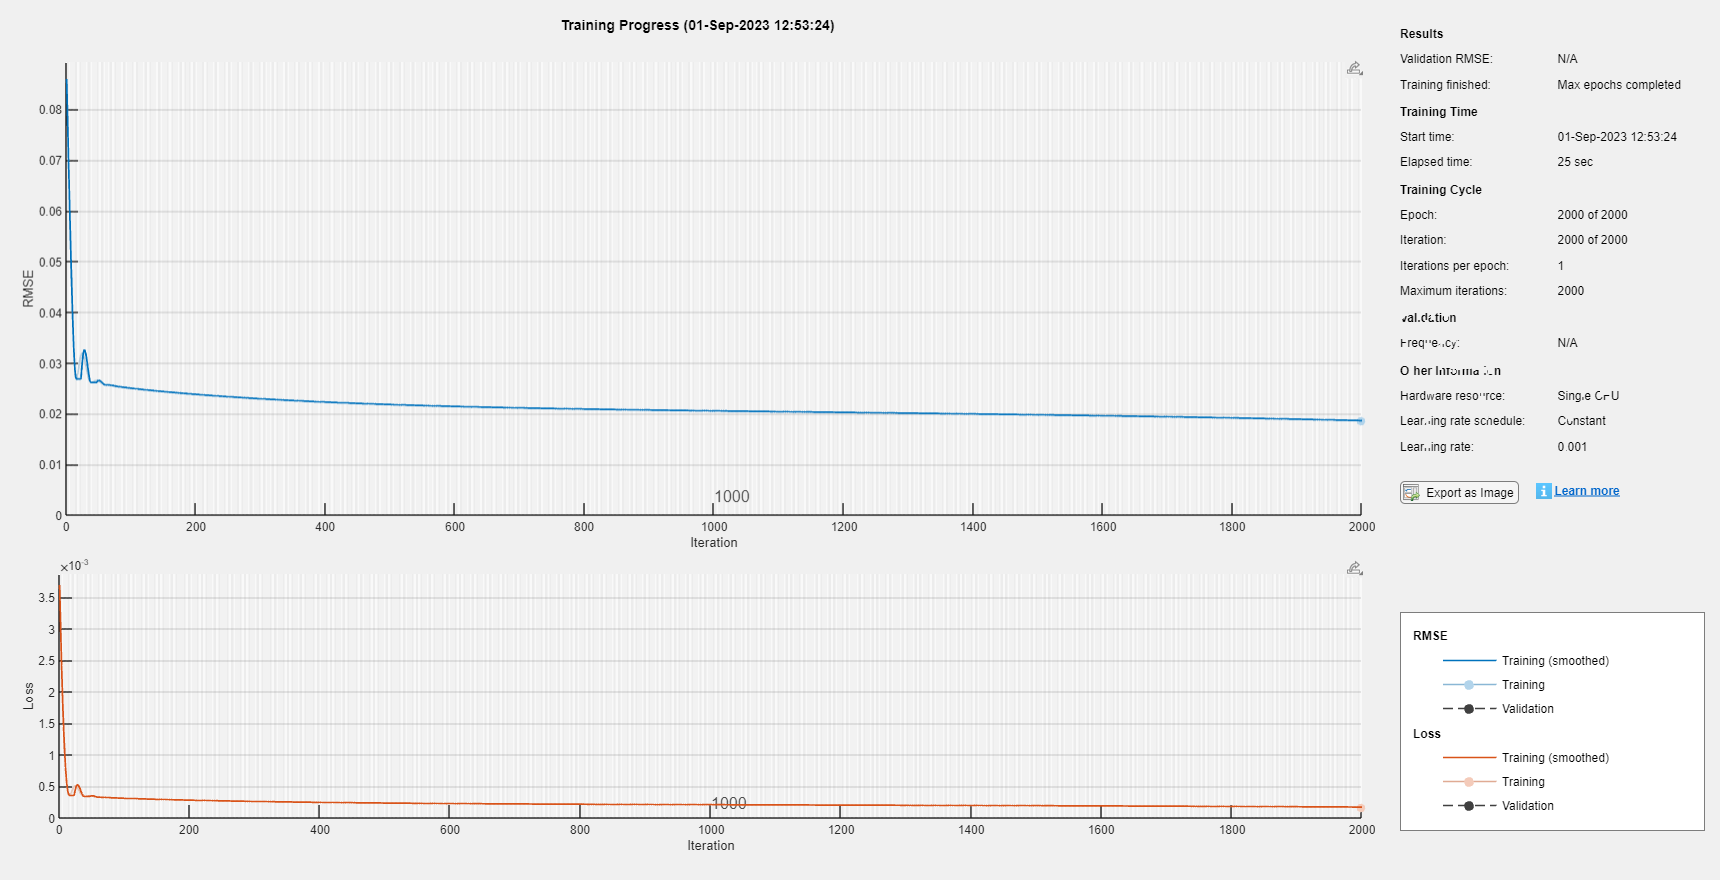

layers = [
    sequenceInputLayer(10,"Name","input")
    fullyConnectedLayer(2,"Name","fc_2")
    fullyConnectedLayer(2,"Name","fc")
    tanhLayer("Name","tanh")
    fullyConnectedLayer(2,"Name","fc_1")
    fullyConnectedLayer(1,"Name","fc_3")
    regressionLayer("Name","regressionoutput")];

% Set options for train 
options = trainingOptions("adam", ...
    MaxEpochs=2000, ...
    Verbose=false, ...
    Plots="training-progress");

% Train model to dataset 
net = trainNetwork(table2array(trainData(:,1:10))', table2array(trainData(:,11))', layers,options);

% Find R^2 for neural net 
y_val = predict(net,table2array(testData(:,1:10))');
r = corrcoef(y_val',table2array(testData(:,11)));
r = r(1,2);
R_squared_net = r^2;
fprintf("R squared: %.2f", R_squared_net)

R squared: 0.38

#### Support Vector Regression

mdl_vec = fitrsvm(trainData(:,1:10),trainData(:,11)) 

mdl_vec =   RegressionSVM
           PredictorNames: {'Layer Height'  'Wall Thickness'  'Infill Density'  'Infill Pattern'  'Nozzle Temperature'  'Bed Temperature'  'Print Speed'  'Material'  'Fan Speed'  'Roughness'}
             ResponseName: 'Tension Strength'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [47×1 double]
                     Bias: 0.1907
         KernelParameters: [1×1 struct]
          NumObservations: 55
           BoxConstraints: [55×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [55×1 logical]
                   Solver: 'SMO'


  Properties, Methods


% Make predictions using the model and test data
pred_vec = predict(mdl_vec,testData(:,1:10));
% Find the R squared value between the predictions and actual data
r = corrcoef(pred_vec,table2array(testData(:,11)));
r = r(1,2);
R_squared_svr = r^2;
fprintf("R squared: %.2f", R_squared_svr)

R squared: 0.29

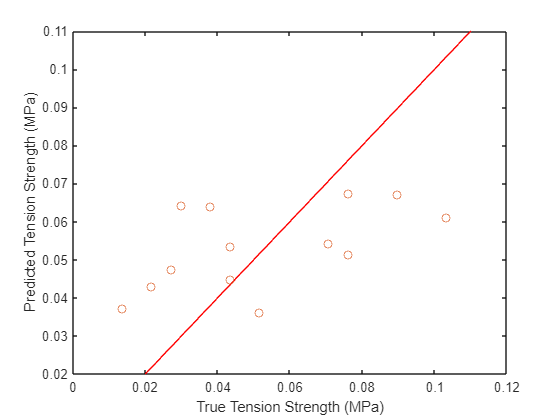

% Graph data
figure;
testData_graph = table2array(testData(:,11));
plot([0.02, 0.11], [0.02,0.11], 'r-'); 
hold on
scatter(testData_graph,pred_vec)
xlabel("True Tension Strength (MPa)")
ylabel("Predicted Tension Strength (MPa)")

% Recalculate predicted values for PLA
dfpl = (testData.Material < 0.005) == 0;
test_pl = testData(dfpl,:)

test_pl = 5×12 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     0.00027174       0.0027174           0.13587         0.0054348            0.54348              0.16304          0.32609      0.0054348           0      0.48913      

% Run three tests on Pla materials 
pl_net_pred = predict(net,table2array(test_pl(:,1:10))');
predictions_pl = predict(mdl,test_pl(:,1:10));
pred_vec_pl = predict(mdl_vec,test_pl(:,1:10));

% Now do it for Abs 
test_ab = testData(~dfpl,:)

test_ab = 8×12 table
    Layer Height    Wall Thickness    Infill Density    Infill Pattern    Nozzle Temperature    Bed Temperature    Print Speed    Material     Fan Speed    Roughness    Tension Strength    Elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.019022           0.24457         0.0054348            0.61141              0.17663           0.1087      0.0027174    0.067935     0.086957      

% Run three tests on Abs materials 
ab_net_pred = predict(net,table2array(test_ab(:,1:10))');
predictions_ab = predict(mdl,test_ab(:,1:10));
pred_vec_ab = predict(mdl_vec,test_ab(:,1:10));

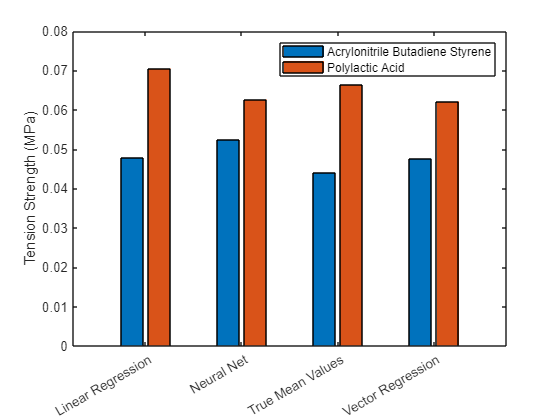

% Create bar graph to compare performance of models 
labels = categorical({'Neural Net','Vector Regression','Linear Regression', 'True Mean Values'});

test_res = [mean(ab_net_pred),mean(pl_net_pred);
    mean(pred_vec_ab), mean(pred_vec_pl);
    mean(predictions_ab), mean(predictions_pl);
    mean(table2array(test_ab(:,11))), mean(table2array(test_pl(:,11)))];

figure
bar(labels,test_res)
legend( "Acrylonitrile Butadiene Styrene", "Polylactic Acid")
ylabel("Tension Strength (MPa)")

**Analysis**

Every regression model is a within a reasonable distance to the true mean. The linear regression model tends to perform the best with its mean predicted tension strength being closest to the true mean values in the bar chart and its r squared value being the highest. 

**Interactive Method**

You can also use [interactive machine learning algorithms](https://www.mathworks.com/campaigns/offers/next/5-interactive-apps-for-machine-learning.html) under the APPS tab to model, fit, and label data. 

function statistics = statistics(data)
    statistics.count = numel(data); % count
    statistics.mean = mean(data); % mean
    statistics.std = std(data); % standard deviation
    statistics.min = min(data); % min
    statistics.max = max(data); % max
    statistics.Q1 = prctile(data,25); % 1st quartile (25th percentile)
    statistics.Q2 = prctile(data,50); % 2nd quartile (50th percentile) = median
    statistics.Q3 = prctile(data,75); % 3rd quartile (75th percentile)
end